clearvars;

samples = 500

samples = 500

Ustawienia

Filename = "sin.wav";
Dither_level = -30;
Bit_resolution = 4;

Wczytanie pliku i wygenerowanie szumu

[x, Fs] = audioread(Filename);

wav_size = size(x);
length = wav_size(1);

if wav_size(2) > 1
    x = x(:, 1);
end

white_noise = wgn(length, 1, Dither_level);
pink_noise = pinknoise(length)*0.4;
blue_noise = bluenoise(length, 1)*0.06;

Zsumowanie szumów z nagraniem

x_2 = x + white_noise;
x_3 = x + pink_noise;
x_4 = x + blue_noise;

Zmiana poziomu kwantyzacji

x_quant = quant(x, Bit_resolution, true, 0, 0);
x_quant_2 = quant(x_2, Bit_resolution, true, 0, 0);
x_quant_3 = quant(x_3, Bit_resolution, true, 0, 0);
x_quant_4 = quant(x_4, Bit_resolution, true, 0, 0);


Wyznaczenie szumu kwantyzacji dla nagrania oryginalnego

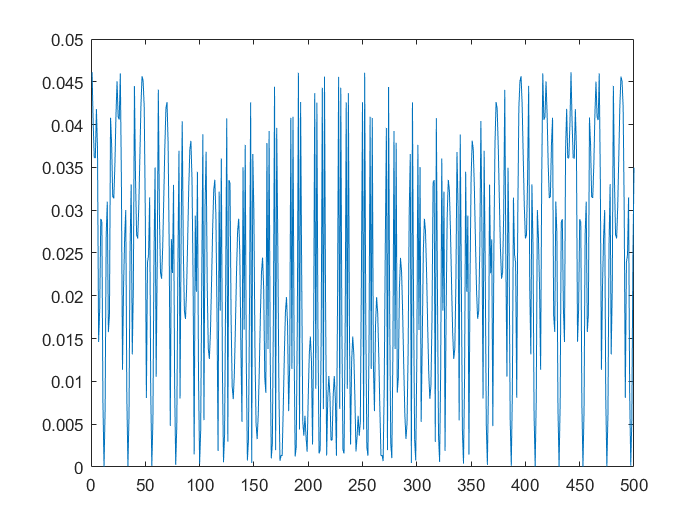

x_diff = abs(x - x_quant');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji"

ans = "Suma szumu kwantyzacji"

sum(x_diff)

ans = 4.7149e+03


x_diff_2 = abs(x - x_quant_2');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji po ditheringu"

ans = "Suma szumu kwantyzacji po ditheringu"

sum(x_diff_2)

ans = 7.8205e+03


x_diff_2 = abs(x - x_quant_3');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji po ditheringu"

ans = "Suma szumu kwantyzacji po ditheringu"

sum(x_diff_2)

ans = 6.2471e+03

Wyznaczenie FFT

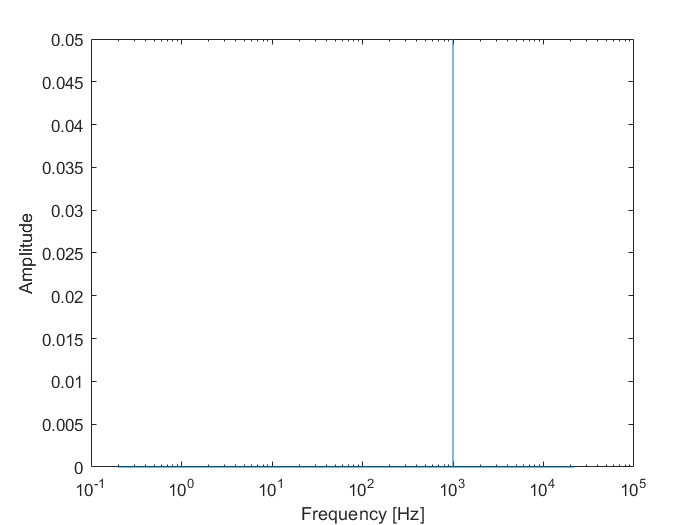



figure(1)
[y, P] = fft_plot(x, length, Fs);

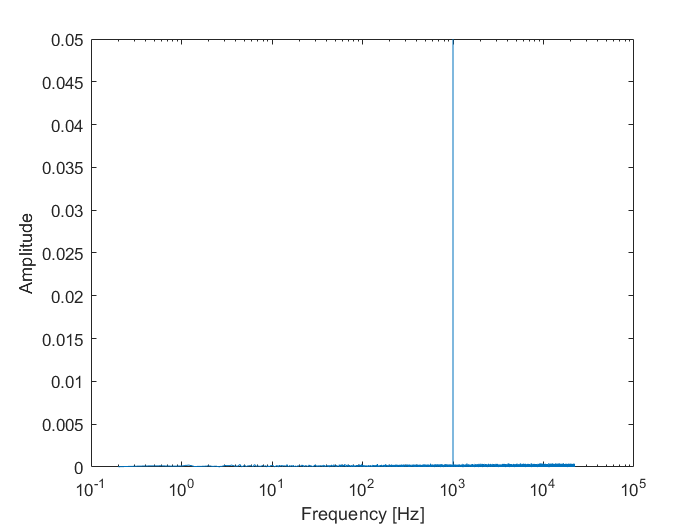

figure(2)
[y_2, P_2] = fft_plot(x_2, length, Fs);

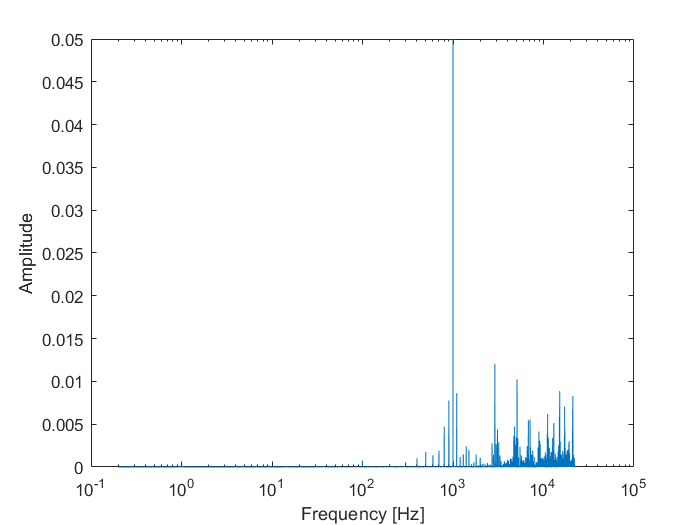


figure(3)
[y_quant, P_quant] = fft_plot(x_quant, length, Fs);

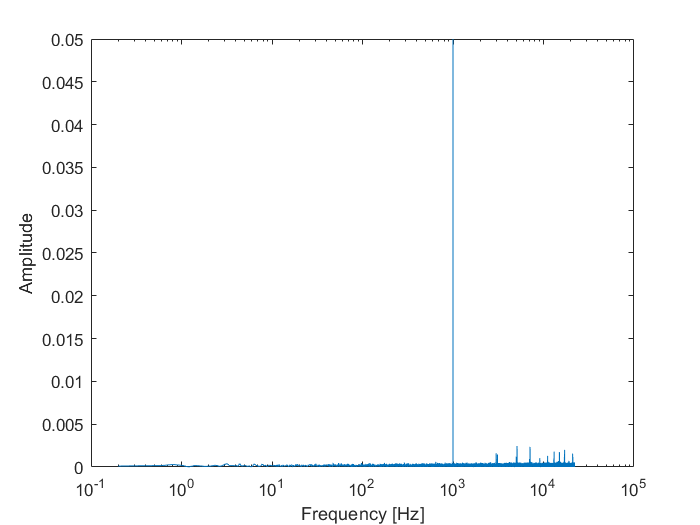

figure(4)
[y_quant_2, P_quant_2] = fft_plot(x_quant_2, length, Fs);

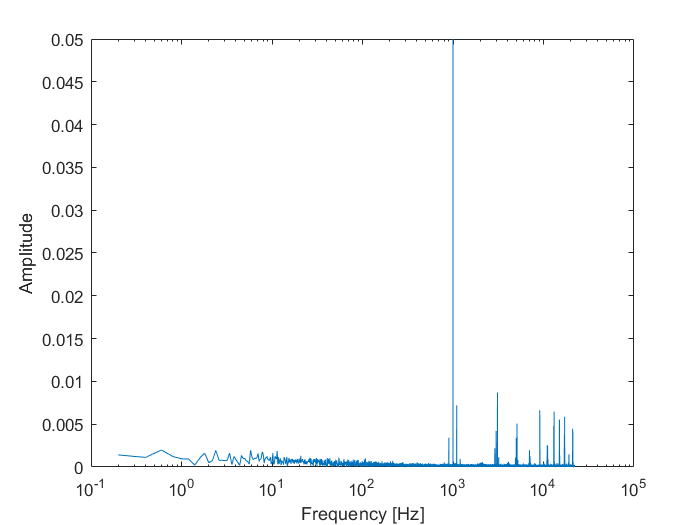

figure(5)
[y_quant_3, P_quant_3] = fft_plot(x_quant_3, length, Fs);

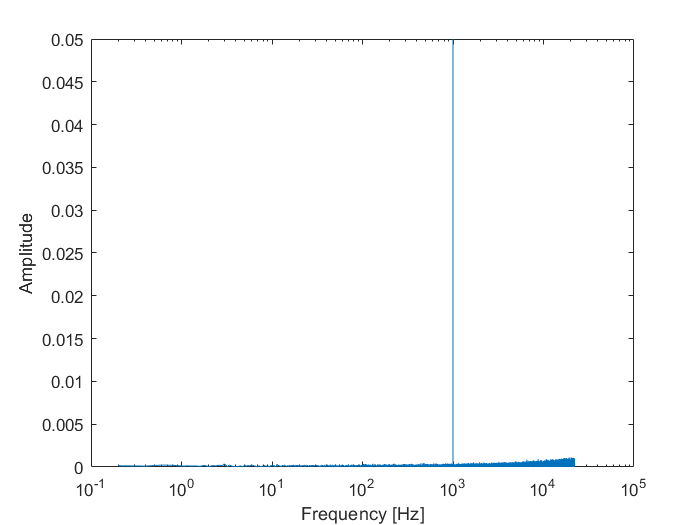

figure(6)
[y_quant_4, P_quant_4] = fft_plot(x_quant_4, length, Fs);



% sound(x_quant, Fs, 8)
% pause(7);
% sound(x_2_quant, Fs, 8)

sum(P)

ans = 0.6982

sum(P_quant)

ans = 1.6073

sum(P_quant_2)

ans = 18.9314

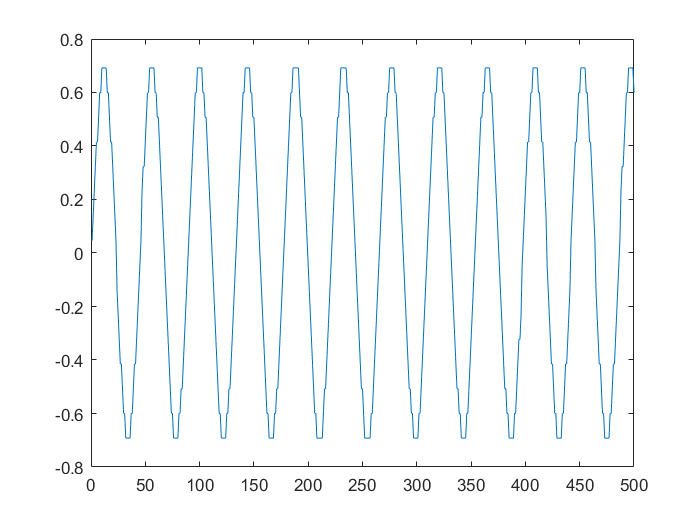


plot(1:samples, x_quant(1:samples))

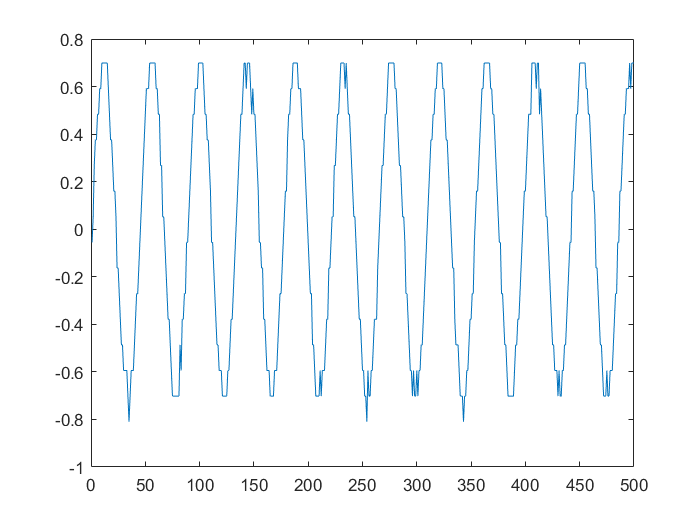

plot(1:samples, x_quant_2(1:samples))

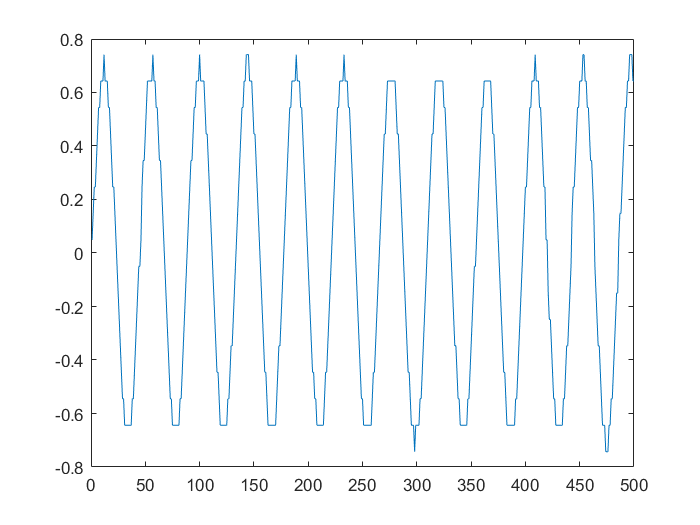

plot(1:samples, x_quant_3(1:samples))

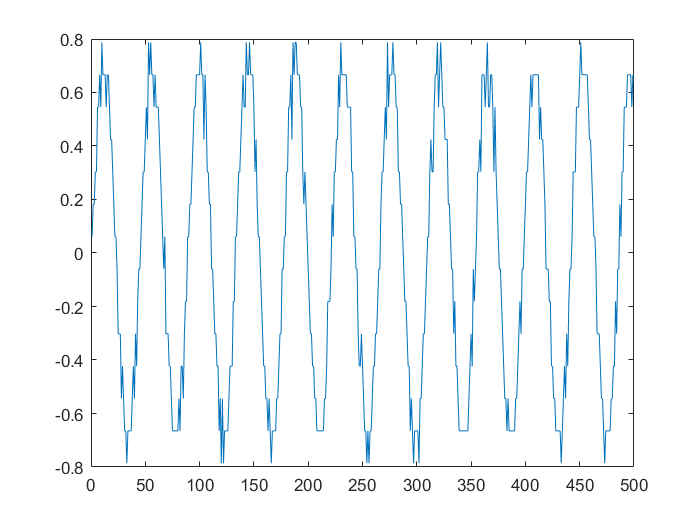

plot(1:samples, x_quant_4(1:samples))